LOAD DATASET 

domian=5;
s=load('matlab.mat');
data=zeros(domian,4);
dd=zeros(domian,1);
data1=s.u;
%%X=data1(:,[1,2,4]);

[a1,b1]=find(data1(:,3)==1);
[a2,b2]=find(data1(:,3)==5);
data2=[a1;a2];
X=data1(data2,[1,2,4]);
%X=corr(X')
Y=data1(data2,3);
X=X([1:50],:);
Y=Y([1:50],:);

rng(1); % For reproducibility



Train an SVM classifier

 Specify a 15% holdout sample for testing 

 standardize the data, and specify that `'g'` is the positive class.

CVSVMModel = fitcsvm(X,Y,'Holdout',0.15,'ClassNames',{'1','5'},...
    'Standardize',true);
CompactSVMModel = CVSVMModel.Trained{1}; % Extract the trained, compact classifier
testInds = test(CVSVMModel.Partition);   % Extract the test indices
XTest = X(testInds,:);
YTest = Y(testInds,:);

 classification error.

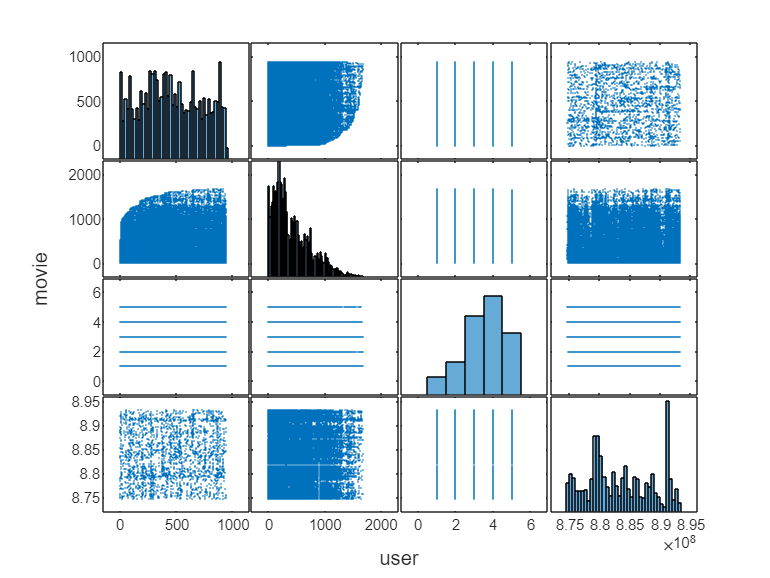

plotmatrix(data1)
xlabel('user')
ylabel('movie')

L = loss(CompactSVMModel,XTest,YTest)

L = 0

X=X([1:100],:);
Y=Y([1:100],:);
SVMModel = fitcsvm(X,Y)

Error using ClassificationSVM.prepareData
Use fitcecoc to train a linear model with more than 2 classes.

Error in classreg.learning.FitTemplate/fit (line 246)
                    this.PrepareData(X,Y,this.BaseFitObjectArgs{:});

Error in ClassificationSVM.fit (l

sv = SVMModel.SupportVectors;
figure
gscatter(X([1:30],1),X([1:30],2),Y)
hold on
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
legend('RATE 1','RATE 5','Support Vector')
hold off

 8% of the test sample.